# Grad CFD HW #7 Problem 2

clear; close all; clc;
tic

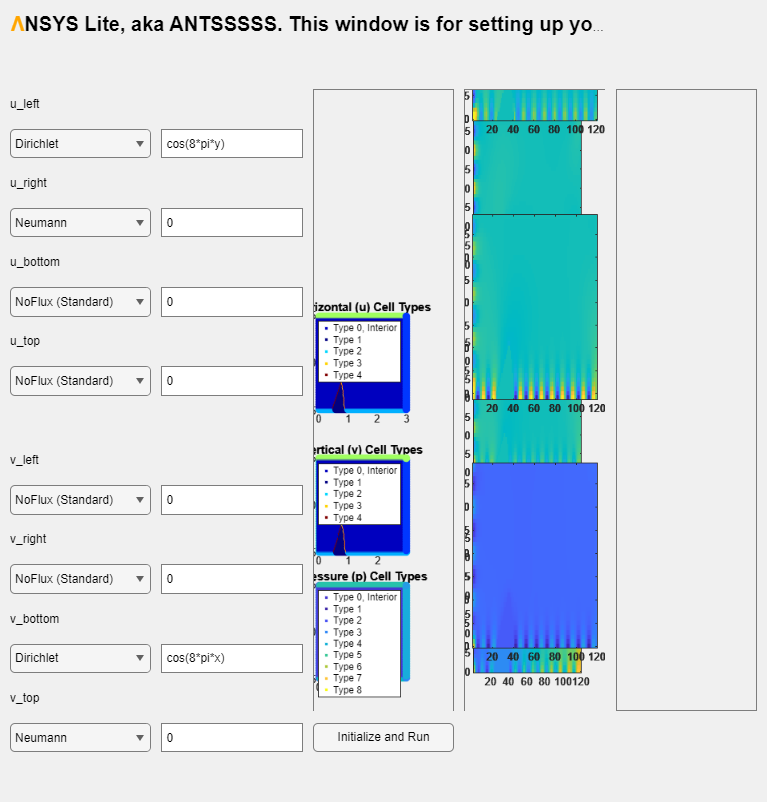

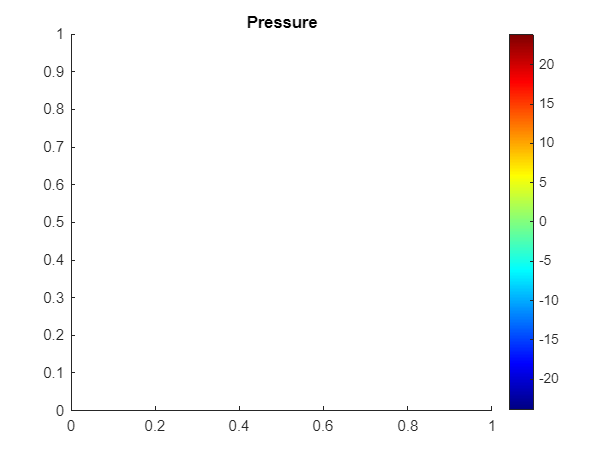

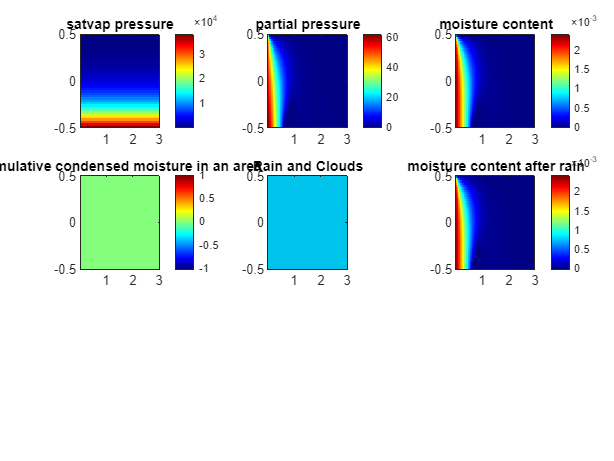

cell_visualizations_on_off =1;
blocked = 0;
rainshadow = 1;
%%%%ideally a geometry gui would set the values currently in
%%%%system_parameters, then once submitted would generate, then gui would
%%%%setup methods then begin once the initialize and run button is clicked
system_parameters                                     %% Set system, geometry, and solver parameters
solver_gui
guess_initialization                                  %% Generate the initial guess for the system


for n = 1:10%:Nt-1                                       %%%%%%%%%%%%%% TIME MARCHING
    time_step_initialization                          %% Set the variables to begin a new time step
    simple_algorithm                                  %% Begin recursive calculation of u^n+1 and v^n+1 using A_u, A_v, and A_p
    heat_transfer_step                                %% Perform a heat transfer step
    plot_store_results                                %% Plot results and store the u^n+1, v^n+1, and p^n+1 fields
    clouds                                            %% Clouds and Rain
end

toc

Elapsed time is 64.519309 seconds.
